clear; close all; clf;

# GPH 333 - Geomagnetism

Nate Crummett

### Question 1

#### A)


$$\textbf{B}_{v} = -2 M sin( \lambda_{m})/r^3$$



$$\textbf{B}_{h} = M cos(\lambda_{m})/r^3$$


Inclination is the angle between the veritcal and the horizontal component of the magnetic field. Thus


$$tan({I}) = \textbf{B}_{v} / \textbf{B}_{h}$$


Which leads to


$$tan(I) = -2 tan(\lambda_{m})$$


This is the relationship between inclination$I$and latitude $\lambda_{m}$.

#### B)

Using elementary trigonometry, the total magnetic intensity $\textbf{B}$ is


$$\textbf{B}^2 = \textbf{B}_{v}^2 + \textbf{B}_{h}^2$$



$$\textbf{B}^2 = 4 M^2 sin^2(\lambda_{m})/r^6 + M^2 cos^2(\lambda_{m})/r^6$$



$$\textbf{B} = (M/r^3) \sqrt[]{4sin^2(\lambda_{m}) + cos^2(\lambda_{m})}$$



$$\textbf{B} = (M/r^3) \sqrt[]{3sin^2(\lambda_{m}) + 1}$$


### Question 2

#### A)

If $I = 45$, we need to find $\lambda_{m}$. Rearranging the equation in **1A** we can find an expression to solve.


$$tan(\lambda_{m}) = (-1/2)tan(I)$$



$$\lambda_{m} = atan((-1/2)tan(I))$$


I = -45; %degrees
lambda_m = atand(-1/2*tand(I));
disp("The magnetic field dips 45 degrees at " + (lambda_m) + " degrees magnetic latitude")

The magnetic field dips 45 degrees at 26.5651 degrees magnetic latitude


clear I lambda_m

Incliniation is into the ground, so the answer comes out positive.

#### B)

When $\lambda_{m}$ is 45 degrees, we need to solve $I$. Rearranging the equation in **1A** we can find an expression to solve.


$$tan(I) = -2 tan(\lambda_{m})$$



$$I = atan(-2 tan(\lambda_{m}))$$


lambda_m = 45; %degrees
I = atand(-2*tand(lambda_m));
disp("The inclination at 45 degrees magnetic latitude is " + (I) + " degrees")

The inclination at 45 degrees magnetic latitude is -63.4349 degrees


clear I lambda_m

This negative means into the ground.

#### C)

The geocentric axial dipole is alligned with Earth's rotation axis. Thus the magnetic latitude is equal to the geographic latitude.

### Question 3

#### A)

The geomagnetic pole is at 79.7 N and 71.8 W. Tilt is zero when the dipole is alligned with the geographic axis.

N = 79.7; W = 71.8;
geographic_N = 90;
tilt = geographic_N - N;
disp("The tilt of the dipole is " + tilt + " degrees from the axis of rotation")

The tilt of the dipole is 10.3 degrees from the axis of rotation


#### B)

To find the southern geomagnetic pole, we need to convert the latitude and longitude of the northern geomagnetic pole,

S = N + 180; S = mod(S,90);
E = 360 - (W + 180);
disp("The southern geomagnetic pole is at " + S + " degrees S and " + E + " degrees E")

The southern geomagnetic pole is at 79.7 degrees S and 108.2 degrees E


clear N E S W tilt geographic_N

### Question 4

#### A)

I am going to reference this image, and treat each case seperately.

%% INSERT geodetic image %%

The first point is at$11^{\circ} S$ and $70^{\circ} W$. It lies on the great circle connnecting the geomagnetic pole and geographic pole. Therefore, declination is $0^{\circ}$, which is called the agonic line. The inclination for this position can be calculated with the expression derived in **2B**. 

geographic_N = 90; geomagnetic_N = 79; 
diff = geographic_N - geomagnetic_N;
S_11 = -11; % geographic degrees, relative to N
lambda_m =  S_11 + diff; % geomag degrees
I = atand(-2*tand(lambda_m));
disp("The inclination of the geomagnetic field for the first point is " + I + " degrees")

The inclination of the geomagnetic field for the first point is 0 degrees


clear I lambda_m S_11

This makes sense because we are on the geomagnetic equator.

The second point is at $0^{\circ} N$ and $20^{\circ} E$. This is a $90^{\circ}$ rotation around the globe, so the declination is now at a maximum. The angle between the points is $11^{\circ}$ in the image, so that is our declination. Facing the geomagnetic north pole, the geomagnetic pole is west of the geographic pole, do the decination is negative. Since we are still on the geomagnetic equator (ie $\lambda_{m} = 0$), the inclination will still be zero.

The final point is at $56^{\circ} N$ and $110^{\circ} E$. This is another $90^{\circ}$ rotation around the globe. We are now back on the great circle that connects the geographic and geomagnetic poles. Therefore, declination is once again $0^{\circ}$. However, we are no longer on the geomagnetic equator. So we use the equation from **2B**.

N_56 = 56;
lambda_m = N_56 - diff;
I = atand(-2*tand(lambda_m));
disp("The inclination at 56 degrees N and 110 degrees E is " + round(I,2,'decimals') + " degrees")

The inclination at 56 degrees N and 110 degrees E is -63.43 degrees


clear I N_56 diff lambda_m geomagnetic_N geographic_N

As before, the negative means into the ground.

#### B)

Earth is much better approximated by a phere than an ellipsoid. Because of the our measurements in the real world will not exactly match the values in **4A**. But more importantly, Earth's magnetic field is not a perfect dipole. Everything above assumes that it is, so in the real world our measurements will reflect the complexity of whatever multi-pole combination is really happening down there.

#### C)

For the geocentric axial dipole, the geographic pole and the geomagnetic pole are alligned. This means for alll three readings, the declination will be $0^{\circ}$. We need to calculate the inclination for each spot wiith the equation from **2B**. For the feocentric axial dipole, geographic latitude equals the geomagnetic latitude.

latitude_GAD = [-11 0 56]';
I = atand(-2*tand(latitude_GAD));
disp("The inclination at first, second, and third points for a geocentric axial dipole model") 

The inclination at first, second, and third points for a geocentric axial dipole model


disp("is " + round(I(1),2,'decimals') + " degrees, " + I(2) + " degrees and " + round(I(3),2,'decimals') + " degrees respectively")

is 21.24 degrees, 0 degrees and -71.36 degrees respectively


clear I latitude_GAD

### Question 5

%% Loading in all, normal, and reverse data
opts = spreadsheetImportOptions("NumVariables", 2);
opts.Sheet = "all";
opts.DataRange = "A1:B183";
opts.VariableNames = ["End", "Begin"];
opts.VariableTypes = ["double", "double"];
allRTS = readtable("C:\Users\rncru\Downloads\GPH333\reversal-time-scale.xls", opts, "UseExcel", false);
clear opts

opts = spreadsheetImportOptions("NumVariables", 2);
opts.Sheet = "normal";
opts.DataRange = "A1:B92";
opts.VariableNames = ["End", "Begin"];
opts.VariableTypes = ["double", "double"];
normalRTS = readtable("C:\Users\rncru\Downloads\GPH333\reversal-time-scale.xls", opts, "UseExcel", false);
clear opts

opts = spreadsheetImportOptions("NumVariables", 2);
opts.Sheet = "reverse";
opts.DataRange = "A1:B91";
opts.VariableNames = ["End", "Begin"];
opts.VariableTypes = ["double", "double"];
reverseRTS = readtable("C:\Users\rncru\Downloads\GPH333\reversal-time-scale.xls", opts, "UseExcel", false);
clear opts

% Note! The current polarity is not yet finished, so do not use it in
% the statistics. It is normal polarity, so only in the normal and all data
% sheets

% units: mya

#### A)

allRTS.Diff = allRTS.Begin - allRTS.End;
normalRTS.Diff = normalRTS.Begin - normalRTS.End;
reverseRTS.Diff = reverseRTS.Begin - reverseRTS.End;

meanDiffAll = mean(allRTS.Diff(2:end));
meanDiffNormal = mean(normalRTS.Diff(2:end));
meanDiffReverse = mean(reverseRTS.Diff);
disp("The mean polarity interval for all, normal, and reverse are " + round(meanDiffAll,3,'decimals') + "0 , " + round(meanDiffNormal,3,'decimals') + " and " + round(meanDiffReverse,3,'decimals') + " ma respectively")

The mean polarity interval for all, normal, and reverse are 0.430 , 0.414 and 0.446 ma respectively


stdDiffAll = std(allRTS.Diff(2:end));
stdDiffNormal = std(normalRTS.Diff(2:end));
stdDiffReverse = std(reverseRTS.Diff);
disp("The standard deviation of polarity interval for all, normal, and reverse are " + round(stdDiffAll,3,'decimals') + "0 , " + round(stdDiffNormal,3,'decimals') + " and " + round(stdDiffReverse,3,'decimals') + " ma respectively")

The standard deviation of polarity interval for all, normal, and reverse are 0.6190 , 0.656 and 0.583 ma respectively


#### B)

Lets assume the disribution is normal and that the standard deviation is a good measure of deviation.

If the current polarity interval (which is normal) falls outside one standard deviation from the mean, we can call the deviation significant.

k = kurtosis(normalRTS.Diff(2:end));
s = skewness(normalRTS.Diff(2:end)); 
disp(meanDiffNormal + " (normal mean) + " + stdDiffNormal + " (normal std) = " + (stdDiffNormal+meanDiffNormal) + " ma")

0.41449 (normal mean) + 0.65631 (normal std) = 1.0708 ma


Since the current polarity interval is 0.78 ma, it falls within the bounds of certainty and is therefore not a significan deviation from normal polarities. How about both normal and reverse polarities?

disp(meanDiffAll + " (normal + reverse mean) + " + stdDiffAll + " (normal + reverse std) = " + (stdDiffAll+meanDiffAll) + " ma")

0.43019 (normal + reverse mean) + 0.61944 (normal + reverse std) = 1.0496 ma


The current interval falls within one standard deviation of the mean for both reverse and normal polarities. I digure nature does not care wether the polarity is normal or reverse - however, I check both because the means are fairly different.

I would like to mention that since this distribution is VERY not gaussian, std and mean are very poor measures to use. The Weibull pdf does not even remotely mimick a gaussian curve.

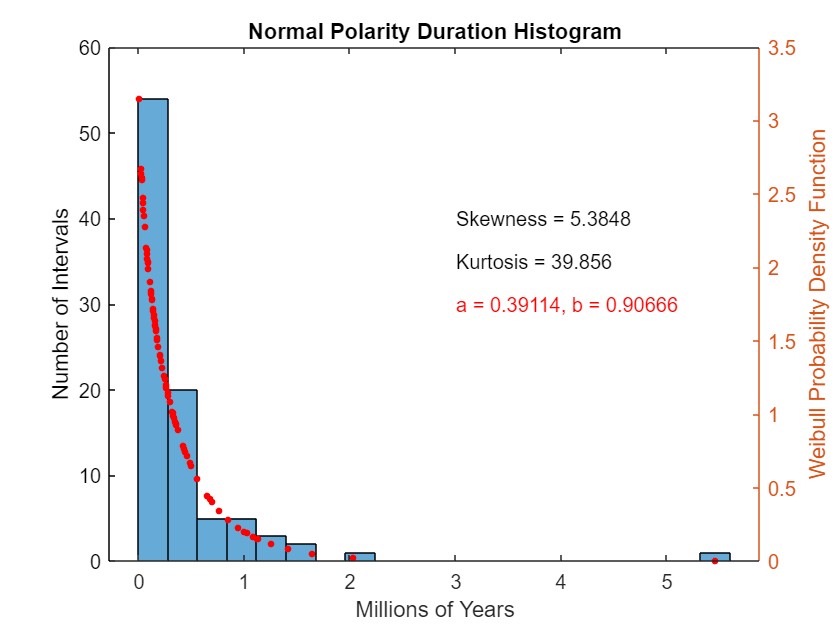

figure(1);
histogram(normalRTS.Diff(2:end),'NumBins',20)
yyaxis left
title 'Normal Polarity Duration Histogram';
xlabel 'Millions of Years'; ylabel 'Number of Intervals';
[a,~] = wblfit(normalRTS.Diff(2:end));
wb = wblpdf(normalRTS.Diff(2:end),a(1),a(2));
hold on
text(3,40,"Skewness = " + s);
text(3,35,"Kurtosis = " + k);
text(3,30,"a = " + a(1) + ", b = " + a(2),'color','r');
hold off
yyaxis right
hold on
plot(normalRTS.Diff(2:end),wb,'r.','MarkerSize',10);
ylabel 'Weibull Probability Density Function';
hold off

clear s k a wb

#### C)

medianDiffAll = median(allRTS.Diff(2:end));
medianDiffNormal = median(normalRTS.Diff(2:end));
medianDiffReverse = median(reverseRTS.Diff);
disp("The median polarity interval for all, normal, and reverse are " + round(medianDiffAll,3,'decimals') + "0 , " + round(medianDiffNormal,3,'decimals') + " and " + round(medianDiffReverse,3,'decimals') + " ma respectively")

The median polarity interval for all, normal, and reverse are 0.2440 , 0.243 and 0.245 ma respectively


#### D)

Median is robust to ouliers, meaning that an outlier will not change the median value until the data is over 50% outliers. On the other hand, mean in not robust to outliers - a single outlier will shift the mean. The variablility in mean is a function of these outliers, and the consistency of the median is a result of its robustness.

#### E)

Since nature presumably does not care about normal or reverse polarity (a conclusion drawn from the close median values) I will use the entire data set.

LTC = allRTS.Diff(1) < allRTS.Diff(2:end); % logical
percentLonger = nnz(LTC)/size(LTC,1)*100;
disp(round(percentLonger,2,'decimals') + "% of all polarity durations have been longer than the current duration")

14.29% of all polarity durations have been longer than the current duration


clear percentLonger LTC

The problem actually asks for the percent of the normal population greater aswell

normalLTC = allRTS.Diff(1) < normalRTS.Diff(2:end);
percentLonger = nnz(normalLTC)/size(normalLTC,1)*100;
disp(round(percentLonger,2,'decimals') + "% of normal polarity durations have been longer than the current duration")

13.19% of normal polarity durations have been longer than the current duration


clear percentLonger normalLTC

#### F)

Filtering out data older than 30 ma and repeating **E **leads to the following

datesMinus30 = allRTS.Begin - 30;
idx30 = datesMinus30 < 0; % started in the last 30 million years
allDiffFilter = allRTS.Diff(idx30);
LTC30 = allDiffFilter(1) < allDiffFilter(2:end);
percentLonger = nnz(LTC30)/size(LTC30,1)*100;
disp(round(percentLonger,2,'decimals') + "% of all polarity durations beginning before 30 ma have been longer than the current duration")

3.31% of all polarity durations beginning before 30 ma have been longer than the current duration


clear datesMinus30 idx30 allDiffFilter LTC30 percentLonger
datesMinus30 = normalRTS.Begin - 30;
idx30normal = datesMinus30 < 0; % started in the last 30 million years
normalDiffFilter = normalRTS.Diff(idx30normal);
LTC30normal = normalDiffFilter(1) < normalDiffFilter(2:end);
percentLonger = nnz(LTC30normal)/size(LTC30normal,1)*100;
disp(round(percentLonger,2,'decimals') + "% of normal polarity durations beginning before 30 ma have been longer than the current duration")

5% of normal polarity durations beginning before 30 ma have been longer than the current duration


#### G)

The data sets with dates younger than 30 million years yeild percents that are much lower than data sets with older data included. This means that the older intervals are on average longer than teh younger values. I think a plausible explanation for this observation is that data quality and abundance decreases with age.

### Bonus

#### 1)

% image here

The pink is my answer. The $I$ needs to be positive for these to hold. So $I$ is assumed to measured positive down from horizontal here.

#### 2)

I kind of got into this above as I was complaining about taking the standard deviation of a skewed data set.

What about looking at the cumulative sum of the Weibull CDF? There are other CDF algorithms to choose from, idk which would be optimal. I just picked this one because I have never tried it before.

Clearly this can be adjusted for the past 30 ma if desired. I am not going to write a report or spend any more time on this.

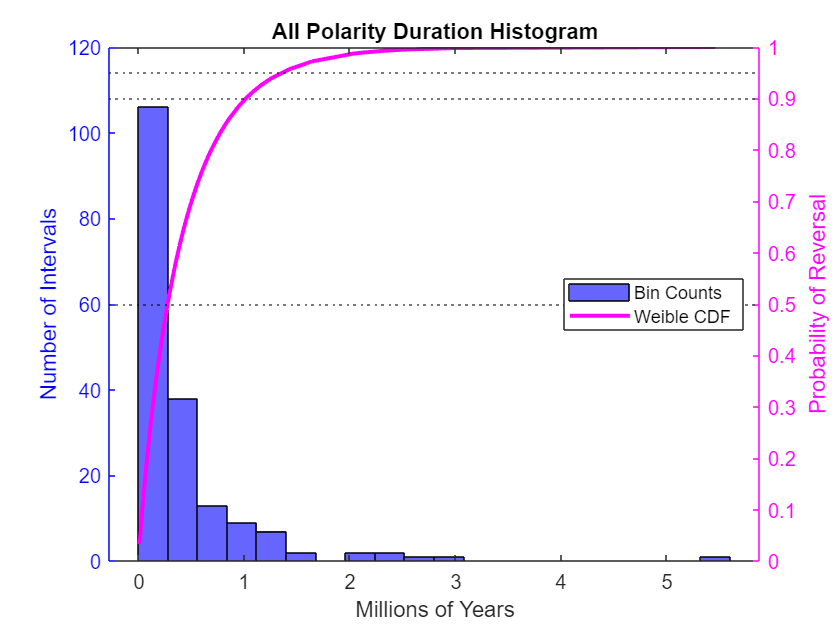

[a,~] = wblfit(allRTS.Diff(2:end));
wbCDF = wblcdf(allRTS.Diff(2:end),a(1),a(2));
figure(3);
colororder({'b','m'})
yyaxis left
histogram(allRTS.Diff(2:end),'NumBins',20)
title 'All Polarity Duration Histogram';
ylabel 'Number of Intervals'; xlabel 'Millions of Years';
yyaxis right
ylabel 'Probability of Reversal';
hold on
[xol,xidx] = sort(wbCDF,1,"ascend");
ma = allRTS.Diff(2:end);
xpoints = ma(xidx);
plot(xpoints,xol,'-','LineWidth',2)
yline(0.5,'k:','LineWidth',0.25)
yline(0.9,'k:','LineWidth',0.25)
yline(0.95,'k:','LineWidth',0.25)
hold off
legend('Bin Counts','Weible CDF','Location','e')